clear all

Day 0 is the start of the dissolution. 

The measurements before Day 0 were of the prewashing of the pellets only (i.e.) not for blank experiments. 

The dissolution study ended on day 15. Samples collected on day 15.1 have been through a 0.45 um filter,  15.2 is through a 0.02 um filter. 

Measurements taken after day 15 are of the rinsing of the vessels in, 2M HNO_3, 1M HNO_3, and three sets of DI for the pellets experiments and blank 1 only. 

x = [-3;1;4;7;15;15.1;15.2;16;17];

exp_err = readtable ('Ce_run3_errors.xlsx', "ReadRowNames",true)

exp_err = 125×27 table
              SampleId            R             AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                    Na23        Mg24         Si29        Cl35          K39         Ca43        Sr88       Rh103_IS_    Cs133    Cs133_1     In115_IS_    La139    La139_1     Ce140     Ce140_1     Pb208     Pb208_1     Re185_IS_    Ce_1140    Ce_1140_1</

exp_data = readtable ('Ce_run3_concentrations.xlsx', "ReadRowNames",true)

exp_data = 126×27 table
                 SampleId               R             AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                  Na23_mg_L_    Mg24_mg_L_    Si29_mg_L_    Cl35_mg_L_    K39_mg_L_    Ca43_mg_L_    Sr88_mg_L_    Rh103_IS_    Cs133_pg_mL_    Cs133_g_L_    In115_IS_    La139_pg_mL_    La139_mg_L_    Ce140_pg_mL_    Ce140_mg_L_    Pb208_pg_mL_    Pb208_mg_L_    Re185_IS_

%Defining sample numbers into sets

% All needed to have the same length so I added in a 'zero' value where
% there was no result 
pellet_4h14K1 = ["EP1";"EP25";"EP36";"EP47";"EP58";"EP69";"EP80"; "EP91";"EP100"];
pellet_4h14K2 = ["EP2";"EP26";"EP37";"EP48";"EP59";"EP70";"EP81"; "EP92";"EP101"];
pellet_4h16K1 = ["EP3";"EP27";"EP38";"EP49";"EP60";"EP71";"EP82"; "EP93";"EP102"];
pellet_4h16K2 = ["EP4";"EP28";"EP39";"EP50";"EP61";"EP72";"EP83"; "EP94";"EP103"];
pellet_2h16K1 = ["EP5";"EP29";"EP40";"EP51";"EP62";"EP73";"EP84"; "EP95";"EP104"];
pellet_2h16K2 = ["EP6";"EP30";"EP41";"EP52";"EP63";"EP74";"EP85"; "EP96";"EP105"];
pellet_2h12K1 = ["EP7";"EP31";"EP42";"EP53";"EP64";"EP75";"EP86"; "EP97";"EP106"];
pellet_2h12K2 = ["EP8";"EP32";"EP43";"EP54";"EP65";"EP76";"EP87"; "EP98";"EP107"];
pellet_blank1 = ["Standard 1";"EP33";"EP44";"EP55";"EP66";"EP77";"EP88"; "EP99";"EP108"];
pellet_blank2 = ["Standard 1";"EP34";"EP45";"EP56";"EP67";"EP78";"EP89";"Standard 1";"Standard 1"];
pellet_blank3 = ["Standard 1";"EP35";"EP46";"EP57";"EP68";"EP79";"EP90";"Standard 1";"Standard 1"];

samplenumber_all = [pellet_4h14K1, pellet_4h14K2, pellet_4h16K1, pellet_4h14K2, pellet_2h16K1, pellet_2h16K2, pellet_2h12K1, pellet_2h12K2, pellet_blank1,pellet_blank2,pellet_blank3];

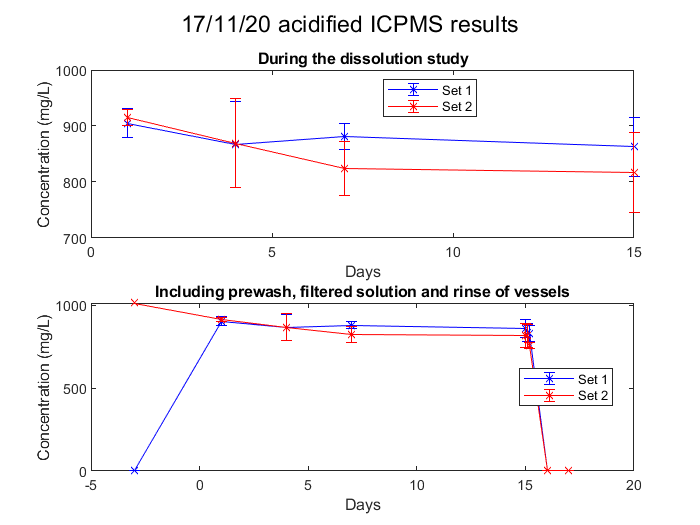

Set1 = pellet_4h14K1;
Set2 = pellet_blank1;

Element = 7;


conc1 = [];
conc2 = [];
err1=[];
err2=[];

for i = 1:size(Set1) 
    s = find(strcmp(Set1(i),exp_data{:,1}));
    conc1 = [conc1; exp_data{s,Element}.*10];
    err1= [err1; exp_data{s,Element}.*10.*exp_err{(s-1),Element}];
end


for i = 1:size(Set2) 
    s = find(strcmp(Set2(i),exp_data{:,1}));
    conc2 = [conc2; exp_data{s,Element}.*10];
    err2= [err2; exp_err{(s-1),Element}*exp_data{s,Element}.*10];
end


% I have multiplied by 10 for the dilution
clf
subplot(2,1,1)

errorbar(x(2:5),conc1(2:5),err1(2:5), 'bx-')
title('During the dissolution study')
xlabel('Days')
ylabel('Concentration (mg/L)')

hold on
errorbar(x(2:5),conc2(2:5),err2(2:5), 'rx-')
legend('Set 1','Set 2', "Location","best")
hold off


subplot(2,1,2)
errorbar(x,conc1,err1, 'bx-')
title('Including prewash, filtered solution and rinse of vessels')
xlabel('Days')
ylabel('Concentration (mg/L)')
hold on
errorbar(x,conc2,err2, 'rx-')
legend('Set 1','Set 2', "Location","best")
hold off


% subplot(3,1,3)
% errorbar(x(8:9),conc1(8:9),err1(8:9), 'bx-')
% title('Two rinses of vessels')
% xlabel('Days')
% ylabel('Concentration (mg/L)')
% hold on
% errorbar(x(8:9),conc2(8:9),err2(8:9), 'rx-')
% legend('Set 1','Set 2', "Location","best")
% hold off

sgtitle('17/11/20 acidified ICPMS results')

But if I do see the concentration falling in the rinse, is that just droplets of solution left over, is it due to pH dependance on solubility, is it precipitated phases gradually getting cleaned.,,,

Now to try and see all of the cerium data on one graph

conc_all= zeros(9,8);
error_all = zeros(9,8);


for j = 1: size(samplenumber_all,2)
    Set =samplenumber_all(:,j);

for i = 1:size(Set) 
    s = find(strcmp(Set(i),exp_data{:,1}));
    conc_all (i,j) = exp_data{s,26}.*10./140000;
    error_all(i,j) = exp_data{s,26}.*(10./140000).*exp_err{(s-1),26};
end
end
% note that I multiply by 10 here to account for dilution 
%and divide by  1000 to convert to grams and 140 to convert to mol



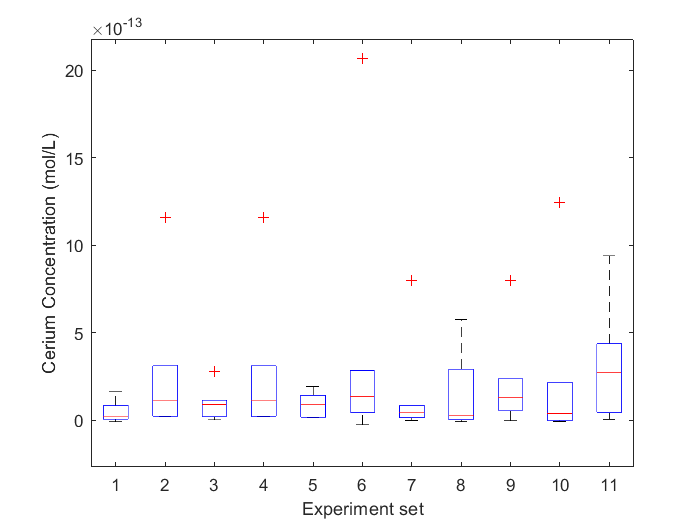

%now to deal with the blanks
blanks  = [mean(reshape(conc_all (2, 9:11),[],1)), mean(reshape(conc_all (3, 9:11),[],1)), mean(reshape(conc_all (4, 9:11),[],1)), mean(reshape(conc_all (5, 9:11),[],1)),mean(reshape(conc_all (6, 9:11),[],1)), mean(reshape(conc_all (7, 9:11),[],1))];
blanks_err = [std(reshape(conc_all (2, 9:11),[],1)), std(reshape(conc_all (3, 9:11),[],1)), std(reshape(conc_all (4, 9:11),[],1)), std(reshape(conc_all (5, 9:11),[],1)),std(reshape(conc_all (6, 9:11),[],1)), std(reshape(conc_all (7, 9:11),[],1))];

clf
boxplot (conc_all (2:7, :))
xlabel('Experiment set')
ylabel('Cerium Concentration (mol/L)')

%clf
%for i =1:size(conc_all,2)
%errorbar(x, conc_all (:,i), error_all(:,i))
%hold on
%end

%legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blank1','blank2','blank3', "Location","best")
%xlabel('Days')
%ylabel('Cerium concentration (mol/L)')
%xlim ([0 15])
%hold off


The point at the end for 2h12k1 was tested twice and confirmed to be at this level, it just is very high

%clf
%for i =1:size(conc_all,2)
%errorbar(x(2:5), conc_all (2:5,i), error_all(2:5,i))
%hold on
%end

%legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blank1','blank2','blank3', "Location","best")
%xlabel('Days')
%ylabel('Cerium concentration (mol/L)')
%hold off

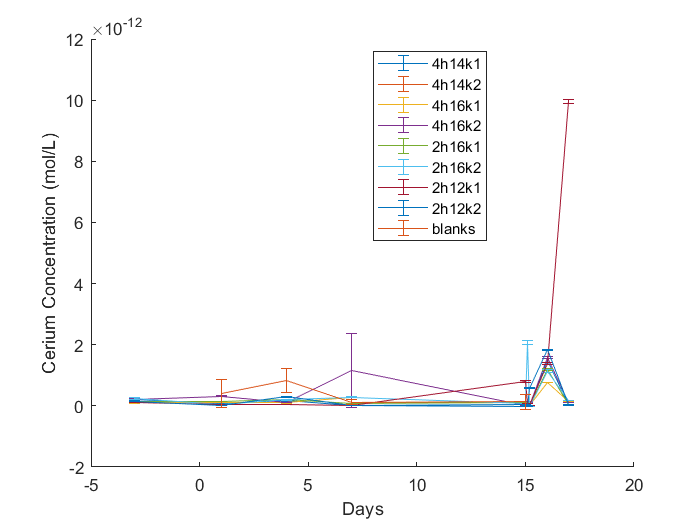

clf
hold all
for i =1:8
errorbar(x, conc_all (:,i), error_all(:,i))
end
errorbar(x(2:5,1), blanks(1:4),blanks_err(1:4))
legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blanks', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
%xlim ([0 15])
hold off

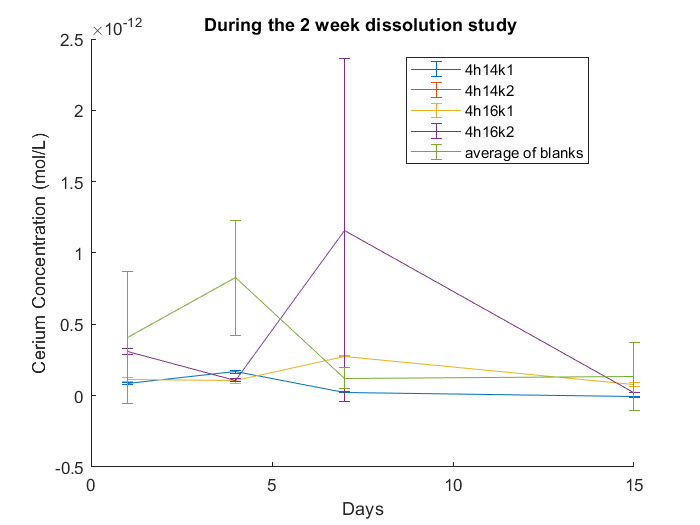



clf
hold all
for i = 1:4
errorbar(x(2:5,1), conc_all (2:5,i), error_all(2:5,i))
end
errorbar(x(2:5,1), blanks(1:4),blanks_err(1:4))
legend('4h14k1','4h14k2','4h16k1','4h16k2','average of blanks', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('During the 2 week dissolution study ')
hold off

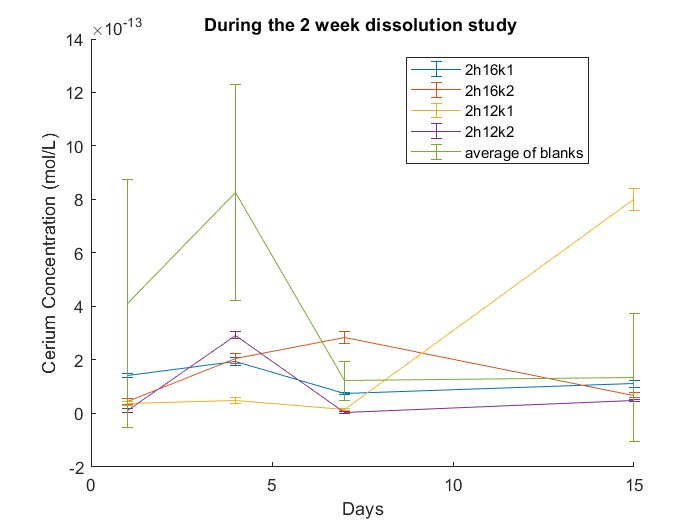


clf
hold all
for i = 5:8
errorbar(x(2:5,1), conc_all (2:5,i), error_all(2:5,i))
end
errorbar(x(2:5,1), blanks(1:4),blanks_err(1:4))
legend('2h16k1','2h16k2','2h12k1','2h12k2','average of blanks', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('During the 2 week dissolution study ')
hold off

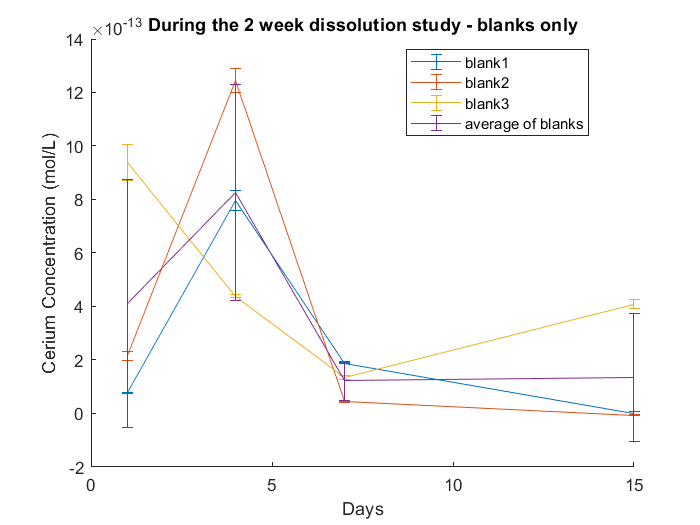


clf
hold all
for i = 9:11
errorbar(x(2:5,1), conc_all (2:5,i), error_all(2:5,i))
end
errorbar(x(2:5,1), blanks(1:4),blanks_err(1:4))
legend('blank1','blank2','blank3','average of blanks', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('During the 2 week dissolution study - blanks only')
hold off

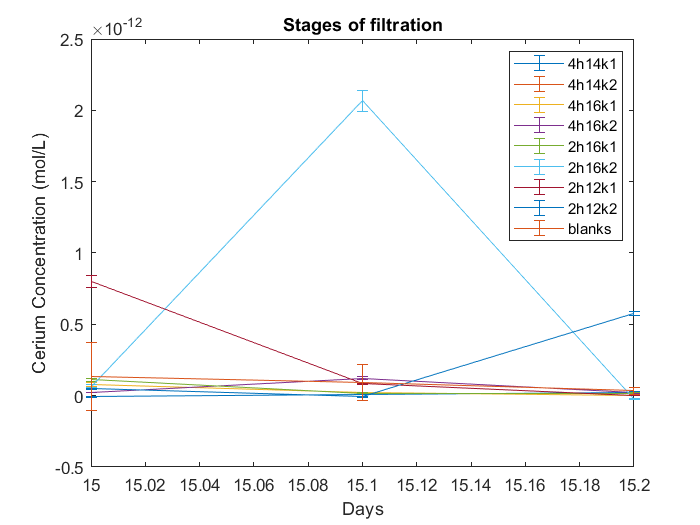


clf
for i = 1:8
errorbar(x(5:7,1), conc_all (5:7,i), error_all(5:7,i))
hold on
end
errorbar(x(5:7,1), blanks(4:6),blanks_err(4:6))
legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blanks', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('Stages of filtration')
hold off

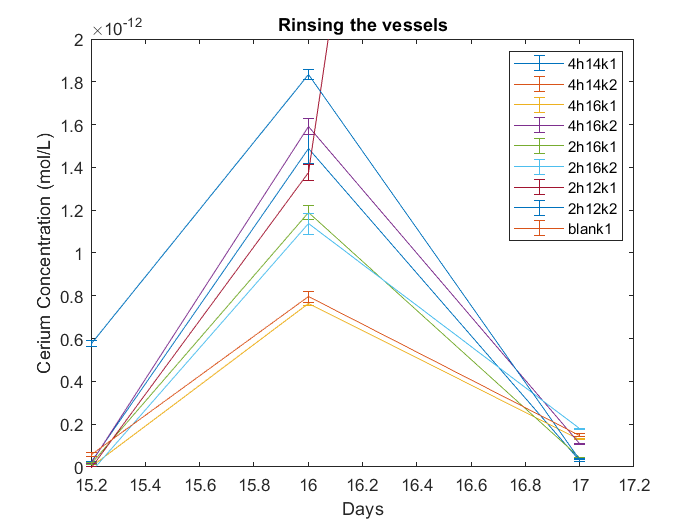


clf
for i = 1:9
errorbar(x(7:9,1), conc_all (7:9,i), error_all(7:9,i))
hold on
end
ylim ([0 2e-12])
legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blank1', "Location","best")
xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('Rinsing the vessels')
hold off


clf 
for i = 1:8
errorbar(x(1:2,1), conc_all (1:2,i), error_all(1:2,i))
hold on
end
%ylim ([0 2e-12])
legend('4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blank1', "Location","best")

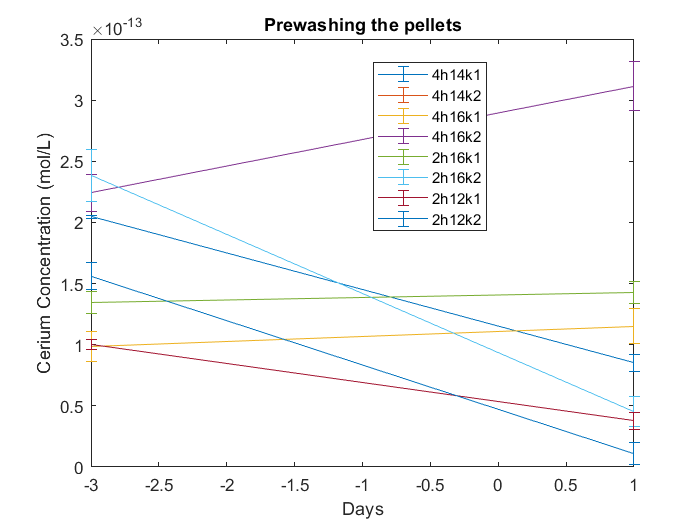

xlabel('Days')
ylabel('Cerium Concentration (mol/L)')
title ('Prewashing the pellets')
hold off

Now I am thinking about how you would work out how much total cerium in each?

%it will be theamount in solution on day 15 *100ml-5*3=85ml and then the amount in the post
%wash *50ml

% note that this first one shouldnt actually be negative. it is 111 counts
% and the blank should really be like 67 counts not the 164 that we had...
% dont know how to fix that really.... it would be hard to recalculate it
% all manually...
X = categorical ({'4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2','blank1','blank2','blank3'});
Ce_dissolved = conc_all (5, 1:11)*0.085;
diss_err = error_all(5, 1:11)*0.085;
%clf
%Ce_precipitated = conc_all (8, 1:11)*0.05; 
%Ce_total = [Ce_dissolved;Ce_precipitated];
%bar(X,Ce_total,'stacked')
%legend('In solution on day 15','Dissolved in the first vessel rinse')
%ylabel('Cerium (mol)')
%title ('Total cerium dissolved')



clf
Ce_precipitated = conc_all (8, 1:11)*0.05 + conc_all (9, 1:11)*0.05;
precip_err = error_all (8, 1:11)*0.05 + error_all (9, 1:11)*0.05

precip_err = 	1.0e+-14 *

    0.3469    0.1919    0.0581    0.1919    0.1796    0.2563    0.5372    0.1291    0.1606       NaN       NaN


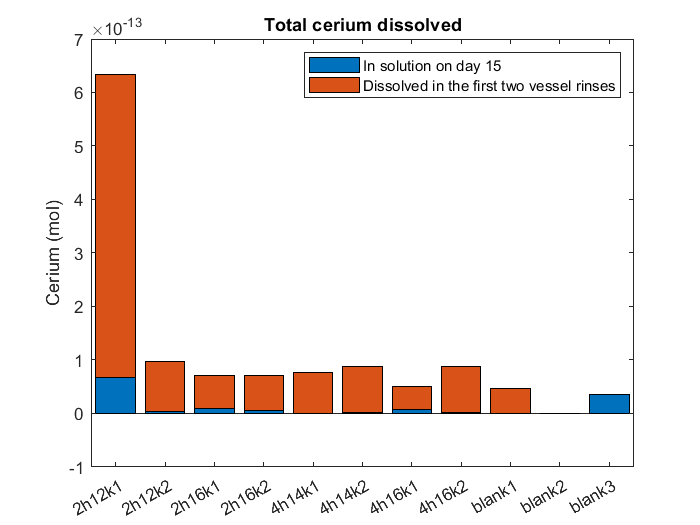


Ce_total = [Ce_dissolved;Ce_precipitated];
err = [diss_err;precip_err];
bar(X,Ce_total,'stacked')
legend('In solution on day 15','Dissolved in the first two vessel rinses')
ylabel('Cerium (mol)')
title ('Total cerium dissolved')

Note that I didnt rinse blank 2 and blank 3 vessels.

Not sure how to handle the uncertainty yet

Now I am thinking about per surface area

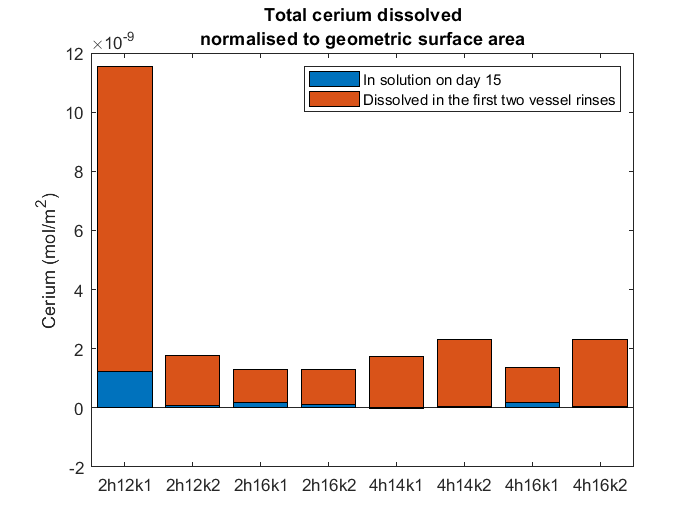

diamtre =[4,4,4,4,5,5,5,5]./1000;
thick = [1.5,1,1,1,1,1,1,1]./1000;
SA =(2.*pi.*(diamtre./2).^2) + (thick.*pi.*diamtre);
X = categorical ({'4h14k1','4h14k2','4h16k1','4h16k2','2h16k1','2h16k2','2h12k1','2h12k2'});
Ce_precipitated_perSA = Ce_precipitated(1:8)./SA;
Ce_dissolved_perSA = Ce_dissolved(1:8)./SA;

Ce_total_perSA= [Ce_dissolved_perSA; Ce_precipitated_perSA];

clf
bar(X(1:8),Ce_total_perSA,'stacked')
legend('In solution on day 15','Dissolved in the first two vessel rinses')
ylabel('Cerium (mol/m^2)')
title ({'Total cerium dissolved','normalised to geometric surface area'})

And now I am thinking about the amounts precipitated in the samples themselves?

unacid_exp_err = readtable ('Ce_run1_errors.xlsx', "ReadRowNames",true)

unacid_exp_err = 177×28 table
              SampleId          R          AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                     Na23         Mg24       Si29        Cl35         K39         Ca43         Sr88      Rh103_IS_    Var15     Cs133      In115_IS_    Var18     La139      Var20     Ce140      Var22     Pb208      Re185_IS_    Var25     Ce_1140

unacid_exp_data = readtable ('Ce_run1_concentrations.xlsx', "ReadRowNames",true)

unacid_exp_data = 177×27 table
                 SampleId             R          AcquisitionTime         QCStatus                                                         DatasetFile                                                                                                     MethodFile                                                  Na23_mg_L_     Mg24_mg_L_    Si29_mg_L_    Cl35_mg_L_    K39_mg_L_     Ca43_mg_L_    Sr88_mg_L_    Rh103_IS_    Cs133_pg_mL_    Cs133_mg_mL_    In115_IS_    La139_pg_mL_    La139_mg_mL_    Ce140_pg_mL_    Ce140_mg_mL_    Pb208_pg_mL_    Pb208_mg_mL_    Re185_I

unacid_conc_all= zeros(9,8);
unacid_error_all = zeros(9,8);


for j = 1: size(samplenumber_all,2)
    Set =samplenumber_all(:,j);

for i = 1:size(Set) 
    s = find(strcmp(Set(i),unacid_exp_data{:,1}));
    unacid_conc_all (i,j) = unacid_exp_data{s,26}.*10./140000;
    unacid_error_all(i,j) = unacid_exp_data{s,26}.*(10./140000).*unacid_exp_err{(s-1),26};
end
end

Ok so now these do not make any sense I think....

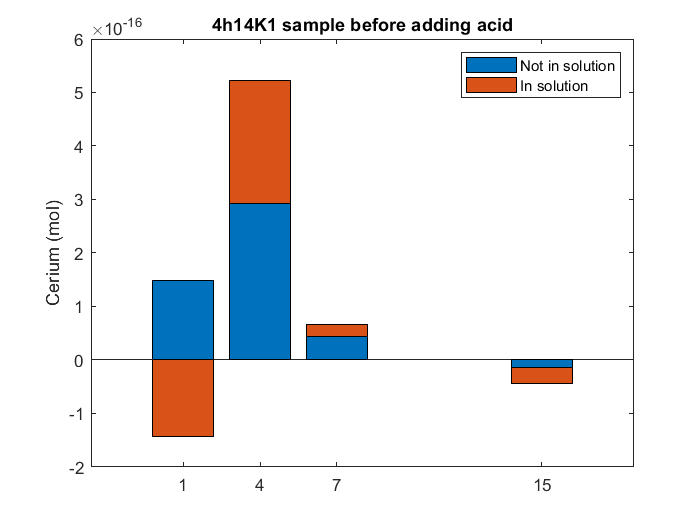

%So in the bar chart lets first look at the first pellet for the whole
%trial

unacid_conc_4k14k1 = conc_all (2:5,1).*0.00175 - unacid_conc_all (2:5,1).*0.002; 
conc_4k14k1 = conc_all (2:5,1).*0.00175;
Ce_total_4h14k1= [conc_4k14k1, unacid_conc_4k14k1];

clf
bar(x(2:5),Ce_total_4h14k1,"stacked")
legend('Not in solution','In solution')
ylabel('Cerium (mol)')
title ({'4h14K1 sample before adding acid'})




% unacid_conc_4k14k2 = conc_all (2:5,2).*0.00175-unacid_conc_all (2:5,2).*0.002; %-conc_all (2:5,1))
% conc_4k14k2 = conc_all (2:5,2).*0.00175;
% Ce_total_4h14k2= [conc_4k14k2, unacid_conc_4k14k2];
% 
% clf
% bar(x(2:5),Ce_total_4h14k2,"stacked")
% legend('Not in solution','In solution')
% ylabel('Cerium (mol)')
% title ({'4h14K1 sample before adding acid'})

% unacid_conc_B1 = conc_all (2:5,9).*0.00175 - unacid_conc_all (2:5,9).*0.002; 
% conc_B1 = conc_all (2:5,9).*0.00175;
% Ce_total_B1= [conc_B1, unacid_conc_B1];
% 
% clf
% bar(x(2:5),Ce_total_B1,"stacked")
% legend('Not in solution','In solution')
% ylabel('Cerium (mol)')
% title ({'B1 sample before adding acid'})

% unacid_conc_2k12k1 = conc_all (2:5,7).*0.00175-unacid_conc_all (2:5,7).*0.002; %-conc_all (2:5,1))
% conc_2k12k1 = conc_all (2:5,7).*0.00175;
% Ce_total_2k12k1= [conc_2k12k1, unacid_conc_2k12k1];
% 
% clf
% bar(x(2:5),Ce_total_2k12k1,"stacked")
% legend('Not in solution','In solution')
% ylabel('Cerium (mol)')
% title ({'2k12k1 sample before adding acid'})
% 
% 
% unacid_conc_2k12k2 = conc_all (2:5,8).*0.00175-unacid_conc_all (2:5,8).*0.002; %-conc_all (2:5,1))
% conc_2k12k2 = conc_all (2:5,8).*0.00175;
% Ce_total_2k12k2= [conc_2k12k2, unacid_conc_2k12k2];
% 
% clf
% bar(x(2:5),Ce_total_2k12k2,"stacked")
% legend('Not in solution','In solution')
% ylabel('Cerium (mol)')
% title ({'2k12k2 sample before adding acid'})

What about figuring out any other elements that might be in the precipitated phase? who else has a differnce on the last day and first rinse?


% note that I multiply by 10 here to account for dilution 
%and divide by  1000 to convert to grams and 140 to convert to mol


now how about with the blanks? I measured just COx in the rerun.... Now this was COx that was just made an left so shouldnt have the same amount of contam? but it wasnt acidified.... we didnt measure cerium in the blank with acid...